subplot(2,2,1)
x = linspace(0,10)

x =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


y1 = sin(x)

y1 =          0    0.1008    0.2006    0.2984    0.3931    0.4839    0.5696    0.6496    0.7230    0.7889    0.8469    0.8962    0.9364    0.9670    0.9878    0.9985    0.9990    0.9893    0.9696    0.9399    0.9007    0.8523    0.7952    0.7300    0.6574    0.5781    0.4928    0.4026    0.3082    0.2107    0.1111    0.0103   -0.0906   -0.1906   -0.2886   -0.3837   -0.4748   -0.5612   -0.6418   -0.7158   -0.7826   -0.8414   -0.8916   -0.9327   -0.9643   -0.9861   -0.9978   -0.9994   -0.9908   -0.9720


plot(x, y1);
title('Subplot 1: sin(x)')

subplot(2,2,2)
y2 = sin(2*x)

y2 =          0    0.2006    0.3931    0.5696    0.7230    0.8469    0.9364    0.9878    0.9990    0.9696    0.9007    0.7952    0.6574    0.4928    0.3082    0.1111   -0.0906   -0.2886   -0.4748   -0.6418   -0.7826   -0.8916   -0.9643   -0.9978   -0.9908   -0.9434   -0.8576   -0.7370   -0.5864   -0.4120   -0.2207   -0.0206    0.1805    0.3742    0.5526    0.7086    0.8358    0.9289    0.9843    0.9997    0.9744    0.9094    0.8075    0.6727    0.5106    0.3277    0.1315   -0.0701   -0.2688   -0.4566


plot(x, y2)
title('Subplot 2: sin(2x)')

subplot(2,2,3)
y3 = sin(4*x)

y3 =          0    0.3931    0.7230    0.9364    0.9990    0.9007    0.6574    0.3082   -0.0906   -0.4748   -0.7826   -0.9643   -0.9908   -0.8576   -0.5864   -0.2207    0.1805    0.5526    0.8358    0.9843    0.9744    0.8075    0.5106    0.1315   -0.2688   -0.6259   -0.8821   -0.9963   -0.9500   -0.7508   -0.4306   -0.0411    0.3550    0.6940    0.9211    1.0000    0.9178    0.6878    0.3471   -0.0496   -0.4383   -0.7563   -0.9526   -0.9955   -0.8781   -0.6192   -0.2607    0.1399    0.5179    0.8125


plot(x, y3)
title('Subplot 3: sin(4x)')

subplot(2,2,4)
y4 = sin(8*x)

y4 =          0    0.7230    0.9990    0.6574   -0.0906   -0.7826   -0.9908   -0.5864    0.1805    0.8358    0.9744    0.5106   -0.2688   -0.8821   -0.9500   -0.4306    0.3550    0.9211    0.9178    0.3471   -0.4383   -0.9526   -0.8781   -0.2607    0.5179    0.9763    0.8311    0.1721   -0.5933   -0.9919   -0.7773   -0.0821    0.6638    0.9993    0.7171   -0.0085   -0.7288   -0.9985   -0.6510    0.0991    0.7878    0.9896    0.5795   -0.1888   -0.8404   -0.9724   -0.5033    0.2770    0.8861    0.9473


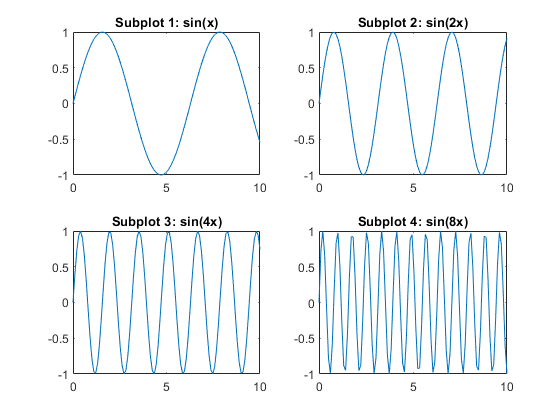

plot(x, y4)
title('Subplot 4: sin(8x)')

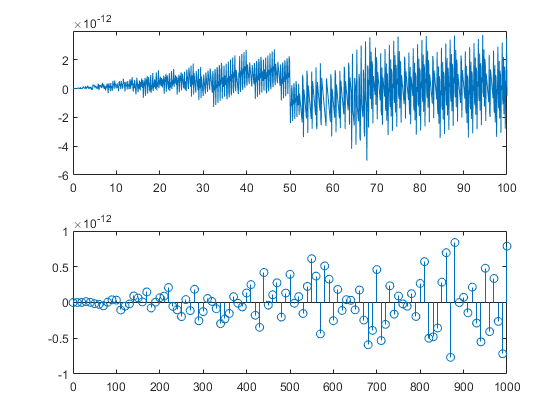

%clc;
%clear all;
%close all;

f=input('Enter Frequency:');
fs=input('Enter Sampling Frequency:');

t=0:0.1:100;
ts=0:10:1000;

x=sin(2*pi*f*t);
subplot(2,1,1);
plot(t,x);

y=sin(2*pi*f*ts/fs);
subplot(2,1,2);
stem(ts,y);  %stem used for discrete

%ramp sequence

n=-5:5;

x = n.*(n>=0)

x =      0     0     0     0     0     0     1     2     3     4     5


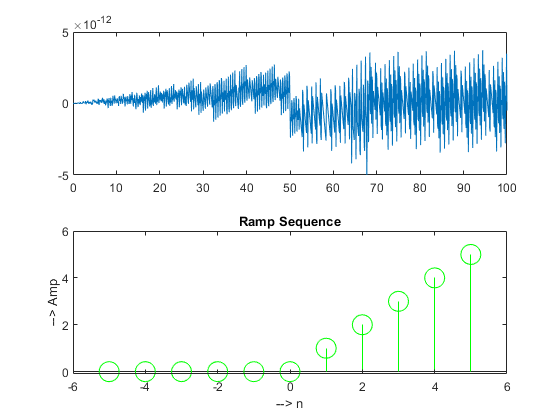


stem(n,x,'go-','MarkerSize',15);
xlim([n(1)-1 n(end)+1]);
ylim([min(x)-0.1 max(x)+1]);
xlabel('--> n');
ylabel('--> Amp');
title('Ramp Sequence');


% for a unit ramp sequnce, peak of amplitude is 1

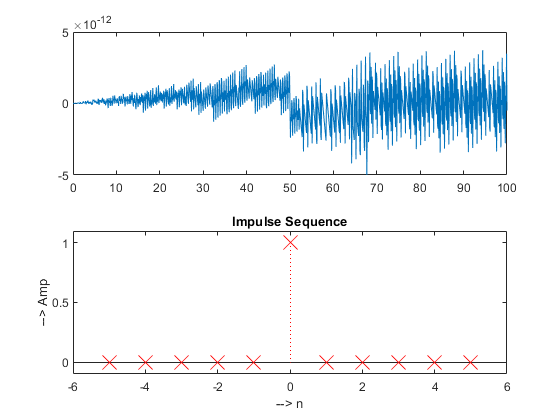

% Unit Impulse Signal
n=-5:5;

x=(n==0);

stem(n,x,'rx:','MarkerSize',15);

xlim([n(1)-1 n(end)+1]);
ylim([-0.1 1.1]);
xlabel('--> n');
ylabel('--> Amp');
title('Impulse Sequence');


% for an impulse signal amplitude at t=0 may or may not be 1

% unit step
n=-5:5;
disp(n);

    -5    -4    -3    -2    -1     0     1     2     3     4     5



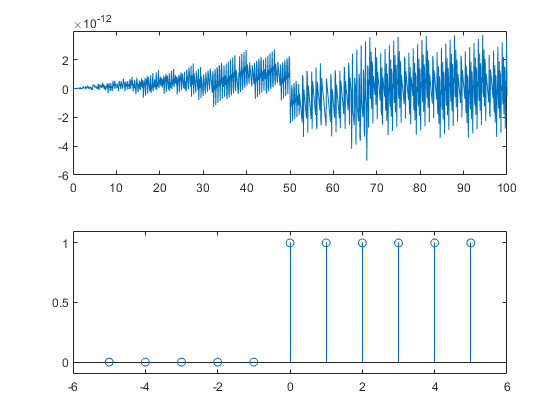

x=[0,0,0,0,0,1,1,1,1,1,1];

stem(n,x);

xlim([-6 6]);
ylim([-0.1 1.1]);


% for a step signal amplitude at t>=1 may or may not be 1